n=0.5

n = 0.5000

state=GDe0FindStates(n,100)

state =     2.7688    2.8416    0.2726
    2.9467    0.4736    0.2696
    1.4192    4.6413    0.6465
    2.9616    0.1579    0.2693
    2.4128    5.5886    0.2996
    1.3302    3.1574    0.3976
    1.7751    5.5254    0.5069
    2.2497    2.8732    0.2935
    3.0357    4.2940    0.2684
    3.0505    3.4731    0.2683


Completed  2  % ...
Completed  3  % ...
Completed  4  % ...
Completed  5  % ...
Completed  6  % ...
Completed  7  % ...
Completed  8  % ...
Completed  9  % ...
Completed  10  % ...
Completed  11  % ...
Completed  12  % ...
Completed  13  % ...
Completed  14  % ...
Completed  15  % ...
Completed  16  % ...
Completed  17  % ...
Completed  18  % ...
Completed  19  % ...
Completed  20  % ...
Completed  21  % ...
Completed  22  % ...
Completed  23  % ...
Completed  24  % ...
Completed  25  % ...
Completed  26  % ...
Completed  27  % ...
Completed  28  % ...
Completed  29  % ...
Completed  30  % ...
Completed  31  % ...
Completed  32  % ...
Completed  33  % ...
Completed  34  % ...
Completed  35  % ...
Completed  36  % ...
Completed  37  % ...
Completed  38  % ...
Completed  39  % ...
Completed  40  % ...
Completed  41  % ...
Completed  42  % ...
Completed  43  % ...
Completed  44  % ...
Completed  45  % ...
Completed  46  % ...
Completed  47  % ...
Completed  48  % ...
Completed  49  % ...


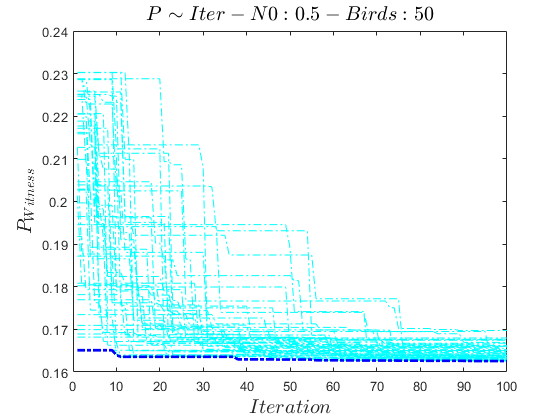

A =    0.162560007904031

B =    1.371121372924429   4.741522117539387   0.978168864239386


C = C(:,:,1) =
   2.711893928326334   4.387699236857252
   2.916981892655842   6.072575743810438
   1.339382167044245   4.493004018541827
   2.128182029850044   0.702031877897160
   2.143958027106160   2.035892445901765
   2.017750049057232   2.141197227586340
   2.443701974972363   2.948533887168074
   3.090517862473117   3.159143450537222
   2.727669925582450   0.596727096212586
   2.901205895399726   0.070203187789716
   2.727669925582450   4.668511988016117
   2.143958027106160   2.281603603165772
   1.796886087471608   2.667721136009209
   2.727669925582450   4.668511988016117
   3.074741865217001   6.107677337705296
   1.607574120398217   3.475057795590945
   2.175510021618391   4.633410394121260
   2.569909953021290   2.457111572640061
   2.143958027106160   2.281603603165772
   2.443701974972363   5.019527926964697
   2.569909953021290   2.457111572640061
   2.569909953021290   1.614673319163469
   1.749558095703261   1.544470131373753
   1.544470131373753   1.404063755794321
 

D =    0.224717973573896   0.224717973573896   0.224717973573896   0.224717973573896   0.224717973573896   0.210525748335938   0.210525748335938   0.210525748335938   0.210525748335938   0.210525748335938   0.175647814589605   0.175647814589605   0.164998376317279   0.164998376317279   0.164998376317279   0.164998376317279   0.164998376317279   0.164998376317279   0.164998376317279   0.164998376317279   0.164998376317279   0.163733700401058   0.163733700401058   0.163733700401058   0.163733700401058   0.163733700401058   0.163733700401058   0.163733700401058   0.163733700401058   0.163733700401058   0.163733700401058   0.163733700401058   0.163733700401058   0.163733700401058   0.163733700401058   0.163733700401058   0.163733700401058   0.163733700401058   0.163733700401058   0.163733700401058   0.163733700401058   0.163733700401058   0.163733700401058   0.163733700401058   0.163733700401058   0.163733700401058   0.163733700401058   0.163733700401058   0.163733700401058   0.16373370040

% plot(n-GDe1Entanglement(0,state(:,1),state(:,2),state(:,3),"Concurrence"))
%  Coefs=GDe0FindStates(0.93,10)
% datasample(Coefs,100)
birdsPSO=50;maxIteration=100;measurement="Witness";
[A,B,C,D]=GDePSO(birdsPSO,2,[0,pi;0,2*pi],'min',maxIteration,n,measurement)

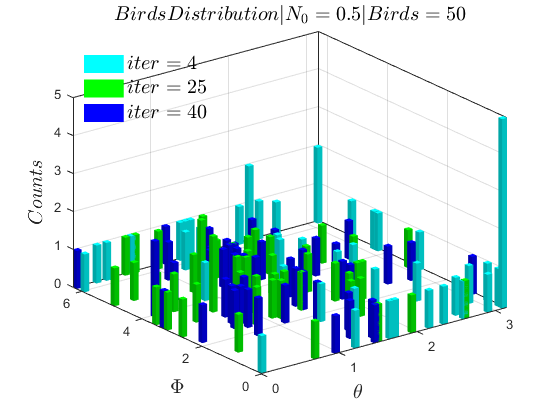

Distribution2dim(C,[floor(maxIteration/25),floor(maxIteration/4),floor(maxIteration/2.5)],num2str(n),num2str(birdsPSO))

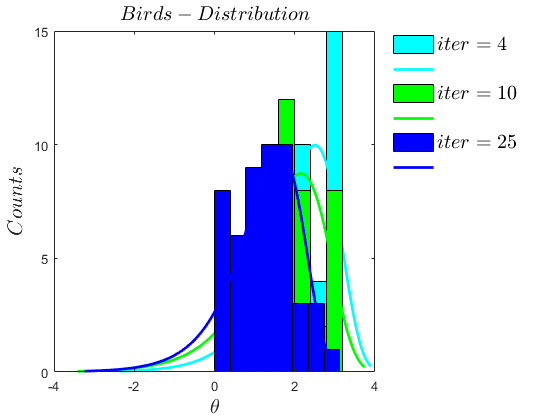

Distribution(C(:,1,:),[floor(maxIteration/25),floor(maxIteration/10),floor(maxIteration/4)],"$\theta$")

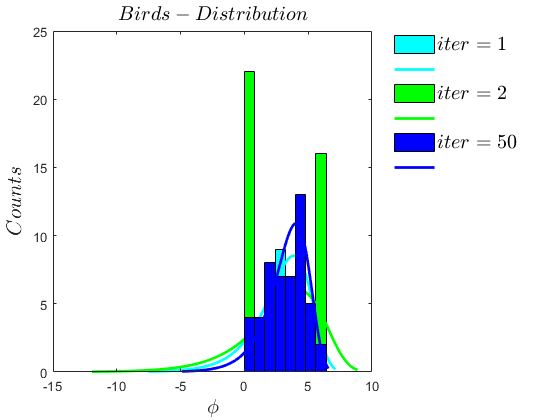

Distribution(C(:,2,:),[floor(maxIteration/100),floor(maxIteration/50),floor(maxIteration/2)],"$\phi$")

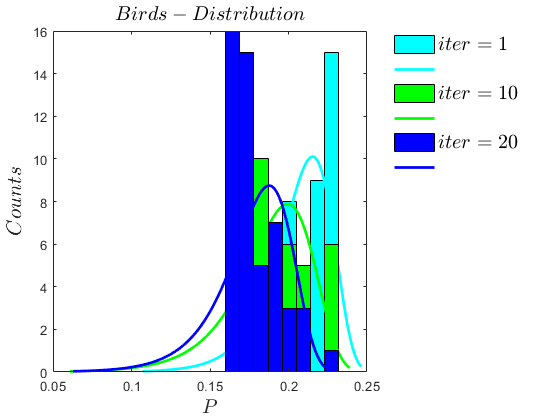

Distribution(D,[floor(maxIteration/100),floor(maxIteration/10),floor(maxIteration/5)],"$P$")

function n=GetN0(Theta,Phi,y)
    n=2.*(y.*sqrt(3+cos(Theta))).*(sin(Theta./2).^2)./(sqrt(2).*(1+y.^2+2.*y.*cos(Theta./2).^3.*cos(Phi)));%for Gamma
end
%---------------------------
function Distribution(C,iterArray,distributionItem)
figure 
h1=histfit(C(:,iterArray(1)),[],'ev');
h1(1).FaceColor="c";
h1(2).Color = h1(1).FaceColor;
hold on
h2=histfit(C(:,iterArray(2)),[],'ev');
h2(1).FaceColor="g";
h2(2).Color = h2(1).FaceColor;
h3=histfit(C(:,iterArray(3)),[],'ev');
h3(1).FaceColor="b";
h3(2).Color =h3(1).FaceColor;
title(strcat("$","Birds","-Distribution","$"),"Interpreter","latex","FontSize",15)
ylabel("$Counts$","Interpreter","latex","FontSize",16)
xlabel(distributionItem,"Interpreter","latex","FontSize",15)
legend('boxoff')
legend(strcat("$iter=",num2str(iterArray(1)),"$"),"",strcat("$iter=",num2str(iterArray(2)),"$"),...
    "",strcat("$iter=",num2str(iterArray(3)),"$"),"","Interpreter","latex","FontSize",15,"Location",'bestoutside')
end
function Distribution2dim(C,iterArray,n,BirdsPSO)
figure 
histogram2(C(:,1,iterArray(1)),C(:,2,iterArray(1)),50,"FaceColor","c")
hold on
histogram2(C(:,1,iterArray(2)),C(:,2,iterArray(2)),50,"FaceColor","g")
histogram2(C(:,1,iterArray(3)),C(:,2,iterArray(3)),50,"FaceColor","b")
legend(strcat("$iter=",num2str(iterArray(1)),"$"),strcat("$iter=",num2str(iterArray(2)),"$"),strcat("$iter=",num2str(iterArray(3)),"$"),"Interpreter","latex","FontSize",15,"Location",'best')
legend('boxoff')
xlabel("$\theta$","Interpreter","latex","FontSize",15)
ylabel("$\Phi$","Interpreter","latex","FontSize",15)
zlabel("$Counts$","Interpreter","latex","FontSize",15)
title(strcat("$","BirdsDistribution","|N_0=",n,"|Birds=",BirdsPSO,"$"),"Interpreter","latex","FontSize",15)
end